# LT2Matlab Converter

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory Lists

Sets paths easily to run, calling functions that import different data types

cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
%cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'

addpath( 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0\', ...
         'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter');


## Code from GitHub

[https://github.com/PeterFeicht/ltspice2matlab.git](https://github.com/PeterFeicht/ltspice2matlab.git)

% Very nice converter from Github!!

% !!!!!!!!!!! Can NOT do steps.. sadly !!!!!!!!!!

addpath('C:\Users\johns\Documents\Github\ltspice2matlab') 
addpath('G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0')
% function raw_data = LTspice2Matlab( filename, varargin )
%    Calling Convention:
%        RAW_DATA = LTspice2Matlab( FILENAME );                  % Returns all variables found in FILENAME
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS );   % Returns only selected variables
%               Set SELECTED_VARS to [] to quickly determine the number and names of variables present in
%               FILENAME without actually loading the variables.
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS, N );
%               Returns variables listed in SELECTED_VARS, with all waveforms downsampled by N. Set N > 1 to
%               load very large data files using less memory, at the price of degraded waveform accuracy and
%               possible aliasing.

filename = '200728 xGAN Kimball Circuit v1.raw'

filename = '200728 xGAN Kimball Circuit v1.raw'

% rawData = LTspice2Matlab( filename, [] )

rawData = LTspice2Matlab( filename, [10])

Error using reshape
Size arguments must be real integers.

Error in LTspice2Matlab (line 672)
                raw_data.variable_mat = reshape(raw_data.variable_mat, mat_size(1), mat_size(2) / num_steps, num_steps);


rawData.variable_name_list % V(n005) is column 10

time = rawData.time_vect;
voltage = rawData.variable_mat;
plot(time, voltage)

% R = 20;
% RString = num2str(R);
% saveName = "KimbalDampingR" + RString +'.mat';
% save(saveName, 'time', 'voltage')

## Frequency Plotters and Extractor

This section converts LTSpice freqeuncy domain outputs to MATLAB and plots them. It takes exported waveforms as such:

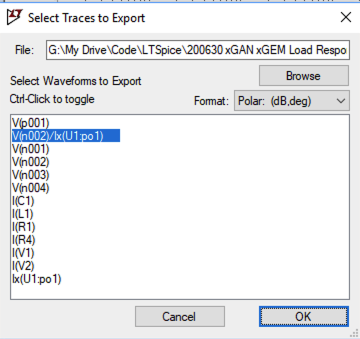

With outputs like this: 

First Line do: "Freq.	V(n002)/Ix(U1:po1)"

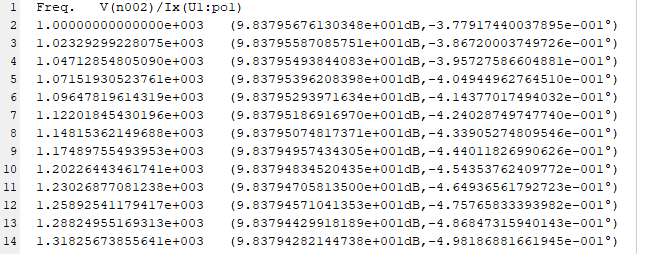

And plots it for us in MATLAB

filenameAdd = '200825 xGAN xGEM Freq Response.txt';
% Single line version exports just raw frequency respnse
% !!!!!!! Must replace top line with 'Freq.	V(n002)/Ix(U1:po1)' !!!!!!!!!
    Data = LT_Freq2Table(filenameAdd)
    % Data = table2array(Data);
    freq = Data(:,'Freq');
    MagZ_out_dB = Data(:,'n002');
    AngZ_out = Data(:,'U1po1');
    freq = table2array(freq);
    MagZ_out_dB = table2array(MagZ_out_dB);
    AngZ_out = table2array(AngZ_out);
    MagZ_out = 10.^(MagZ_out_dB/20)
    
    loglog(freq, (MagZ_out))
    
    samplePt = 1001; %pt 1001 = 100MHz = 124.78298 ohm directly
    freqSample = freq(samplePt)
    zSample = MagZ_out(samplePt) % convert from dB to normal!s
    % z = 1/(2pi*f*C)lead to
    C_eff = 1/(2*pi*freqSample*abs(zSample))
    
    resFreq = 1.0694652e9; %GHz
    % w^2 = 1/LC
    L_eff = 1/((2*pi*resFreq)^2*C_eff)
    save('200701 xGAN Kimball RLC Full Freq Resp', 'freq', 'MagZ_out')


## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

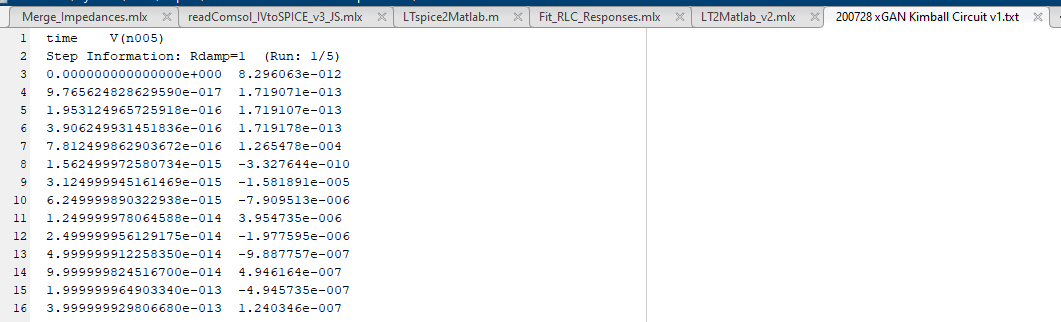

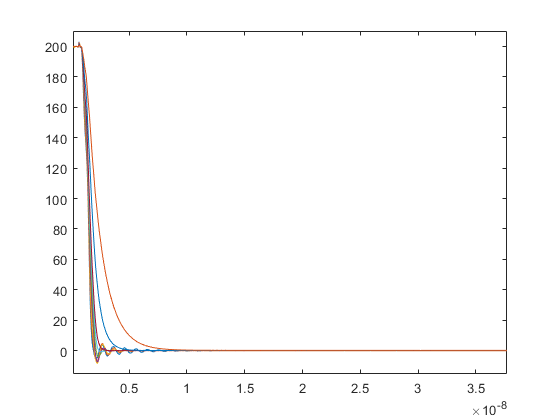

% % % Checks data from current directory with frequency data 
% % Files = dir;
% % checkThis = 2; % which file to read/look at
% % name = Files(checkThis).name;
% 
name = '200728 xGAN Kimball Circuit v4.txt';
fileID = fopen(name,'rt');
formatSpecVars = '%s\t%s';
formatSpecStep = 'Step Information: Rdamp=%f  (Run: %d/%d)';
formatSpecData = '%f\t%f';

    
varName = textscan(fileID, formatSpecVars, 1);  % pulls out variable name
stepName = textscan(fileID, formatSpecStep);    % pulls out run information 
stepR(1) = stepName{1,1};                           % pulls out run resistance
stepMax = stepName{1,3};                         % pulls out max step number
stepData = textscan(fileID, formatSpecData);
stepData = cell2mat(stepData);

% Time axis for interpolation of data
timeRes = 50E-12; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear

% number of points (must round to real number
numIntPts = round(((stepData(end,1)-stepData(1,1))/timeRes)+1); % number of interpolated points

% time vector
interpTime = linspace(stepData(1,1), stepData(end,1), numIntPts);

% interpolates voltages
interpVolt = interp1(stepData(:,1),stepData(:,2),interpTime, interpMethod); %interpolates time

interpVoltAll = zeros(stepMax,numIntPts);
interpVoltAll(1, :) = interpVolt;

% loops through steps
if (1) %multiple steps
    for stepNum = 2:stepMax                             %start from 2 since run 1 above
        stepName = textscan(fileID, formatSpecStep);    % read step line
        stepR(stepNum) = stepName{1,1};                 % extracts resistance     
        stepData = textscan(fileID, formatSpecData);
        stepData = cell2mat(stepData);                  % converts to array

        interpVoltAll(stepNum, :) = interp1(stepData(:,1),stepData(:,2),interpTime);
   
    end
end
plot(interpTime, interpVoltAll)


stepR

stepR = 1×10 int32 row vector
     1     3     5    10    15    20    25    50   100    50


% 
fclose(fileID);
% 
% figure()
% titleText = ['File ', name];
% plot(time, voltage);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);


## Symmetrize Outputs for Fourier Analysis

interpVoltAllDbl = [interpVoltAll, interpVoltAll(1)-interpVoltAll(:,2:end)]

interpVoltAllDbl =   199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.2859  199.7207  202.9219  201.9278  200.2944  199.5959  199.0870  195.7177  187.8227  177.0390  165.6661  155.7239  147.3353  140.9691  135.4051  129.3430  121.2512  109.4991   93.9567   75.8854   56.7965   39.0884   25.0122   15.7899    9.5362    4.8949    2.2109    0.2179   -1.8290   -3.3837   -4.4253   -4.8858   -5.0241   -4.9474   -4.2460   -3.0225   -1.3879    0.2198    1.4999
  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.9970  199.2762  199.7546  202.7626  201.8203  200.1296  199.5084  199.1260  195.8706  188.4366  178.3322  167.6896  158.4137  150.2646  143.9047  138.0459  131.4180  122.7529  110.6715   95.4388   78.3460   60.5889   44.1487   30.9286   21.7319   15.1094    9.8528    6.4186    3.4232    0.1473   -2.6794   -4.7348   -6.1107   -6.9147   -7.3746   -6.9721   -5.7372   -3.8514

interpTimeDbl = [interpTime, interpTime(2:end) + interpTime(end)]

interpTimeDbl = 	1.0e+-7 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


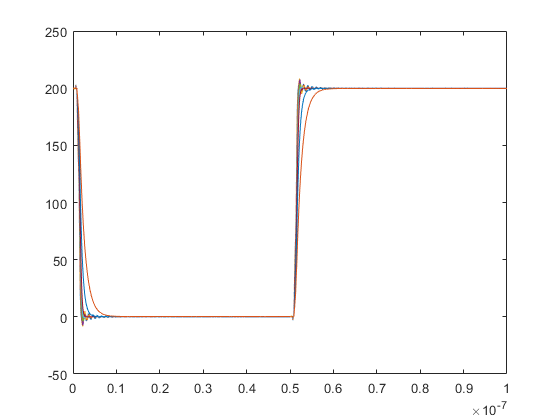

plot(interpTimeDbl,interpVoltAllDbl)


% save symmetrized data
save("200728 xGAN Symmetric Kimball Sweep v4.mat", "stepR", "interpTimeDbl", "interpVoltAllDbl");

## Original Method Direct Read

% % Checks data from current directory with frequency data 
% Files = dir;
% checkThis = 2; % which file to read/look at
% name = Files(checkThis).name;
% 
% fileID = fopen(name,'rt');
% formatSpec = '%f\t%f';
% 
% %A = fscanf(fileID,formatSpec)
% titles = textscan(fileID, '%s\t%s', 1);
% data = textscan(fileID, formatSpec);
% tit1 = titles{1};
% tit2 = titles{2};
% tit1 = tit1{1};
% tit2 = tit2{1};
% 
% time = data(1);
% voltage = data(2);
% time = time{1}';
% voltage = voltage{1}.';
% 
% fclose(fileID);
% 
% figure(1)
% titleText = ['File ', name];
% plot(time, voltage);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);
% 

## Interpolate to constant time step!

% timeRes = 10E-12; % 10ps time resolution
% interpTime = linspace(time(1), time(end), (time(end)-time(1))/timeRes+1);
% interpVolt = interp1(time,voltage,interpTime, 'PCHIP');
% 
% figure(2)
% titleText = ['Interpolated File ', name];
% plot(interpTime, interpVolt);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);